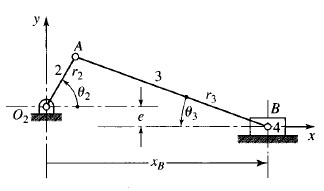

clear all
clc

theta2 = sym('theta_2');
theta3 = sym('theta_3');

r2 = 3; r3 = 8; e = -0.5;
O2x = 0; O2y = 0; 

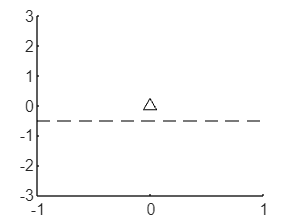

figure()
hold on
plot(O2x,O2y,"^k")
yline(e,"--k")
hold off
ylim([-3 3])

Ax = r2*cos(theta2); %% Joint A
Ay = r2*sin(theta2);
Bx = Ax + r3*cos(theta3) %% Joint B

$$Bx = 3\,\cos\left(\theta_{2}\right)+8\,\cos\left(\theta_{3}\right)$$

By = Ay - r3*sin(theta3)

$$By = 3\,\sin\left(\theta_{2}\right)-8\,\sin\left(\theta_{3}\right)$$

%% This is ONE degree of freedom mechanism, so we can solve theta3 as a function of theta2

Solve the position

eq = e == By

$$eq = -\frac{1}{2}=3\,\sin\left(\theta_{2}\right)-8\,\sin\left(\theta_{3}\right)$$

sol = solve(eq,theta3) %% this is how we solve theta3 as a function of theta2

$$sol = \left(\begin{array}{c} \mathrm{asin}\left(\frac{3\,\sin\left(\theta_{2}\right)}{8}+\frac{1}{16}\right)\\ \pi -\mathrm{asin}\left(\frac{3\,\sin\left(\theta_{2}\right)}{8}+\frac{1}{16}\right) \end{array}\right)$$

theta3_sol = sol(1)

$$theta3\_sol = \mathrm{asin}\left(\frac{3\,\sin\left(\theta_{2}\right)}{8}+\frac{1}{16}\right)$$

BxNew = subs(Bx,theta3,theta3_sol);
ByNew = subs(By,theta3,theta3_sol);

h_link2 = @(t) plot([0 subs(Ax,t)],[0 subs(Ay,t)],".-r","MarkerSize",20)

h_link2 = function_handle with value:
    @(t)plot([0,subs(Ax,t)],[0,subs(Ay,t)],".-r","MarkerSize",20)


h_link3 = @(t) plot([subs(Ax,t) subs(BxNew,t)],[subs(Ay,t) subs(ByNew,t)],".-b","MarkerSize",20)

h_link3 = function_handle with value:
    @(t)plot([subs(Ax,t),subs(BxNew,t)],[subs(Ay,t),subs(ByNew,t)],".-b","MarkerSize",20)


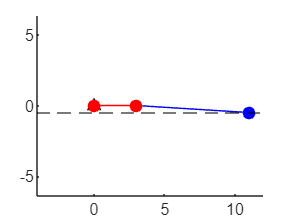


figure()
hold on
plot(O2x,O2y,"^k")
yline(e,"--k")

fanimator(h_link3)
fanimator(h_link2)
hold off

axis equal

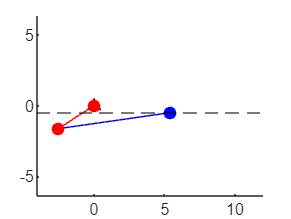

$$Bx = 3\,\cos\left(\theta_{2}\right)+8\,\cos\left(\theta_{3}\right)$$

playAnimation